# Mesh Generation

## Geometry generation with delaunayTriangulation and isInterior

clear;
nodes_geo = [-0.5 -0.5  0.5 0.5  0    0;  
              0.5 -0.5 -0.5 0.5  0 -0.45];
edges_geo =[1:4; 2:4,1];

DT = delaunayTriangulation(nodes_geo', edges_geo');
TF = isInterior(DT);
elements_geo=DT(TF,:)';

## Figure geometry and write data

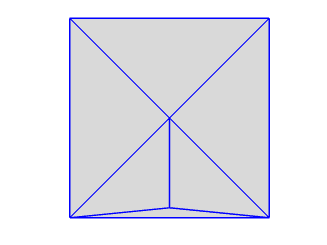

figure; 
patch('Faces',elements_geo','Vertices',nodes_geo','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');
% hold on
% plot(nodes_geo(1, :) , nodes_geo(2, :), 'r.', MarkerSize = 10);
% hold on
% text(nodes_geo(1,:),nodes_geo(2,:), 'n' + string(1:size(nodes_geo,2)));
% hold on
% text((nodes_geo(1, edges_geo(1,:)) + nodes_geo(1, edges_geo(2,:)))/2, ...
%      (nodes_geo(2, edges_geo(1,:)) + nodes_geo(2, edges_geo(2,:)))/2, ...
%     'e' + string(1:size(edges_geo,2)));

axis equal off
exportgraphics(gca,'SquareInteriorNodes-Geo.pdf','ContentType','vector');

geometrywrite(nodes_geo, elements_geo, edges_geo, 'geometry.dat');

## Example 1: Default

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat'); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

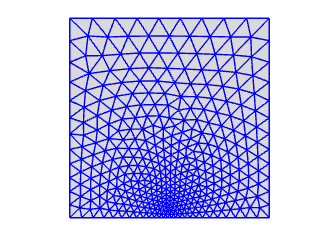

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');
axis equal off
exportgraphics(gca,'SquareInteriorNodes-MeshDefault.pdf','ContentType','vector');

###  Figure Mesh with Bubbles

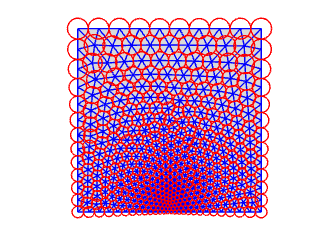

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

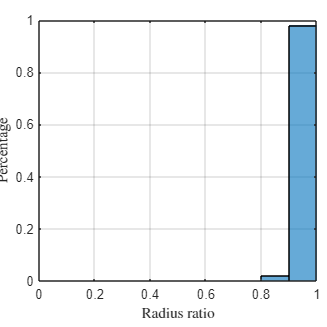

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 2: Hvertex

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hvertex={5,0.02}); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

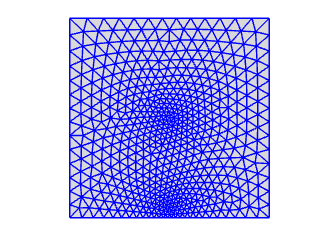

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');
axis equal off
exportgraphics(gca,'SquareInteriorNodes-MeshHvertex.pdf','ContentType','vector');

###  Figure Mesh with Bubbles

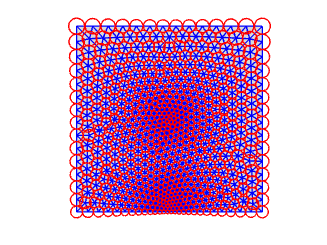

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

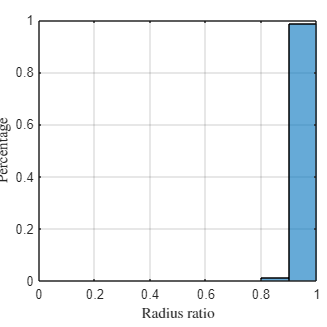

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 3: Hedge

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hedge={4,0.02}, Hvertex={5,0.02}); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

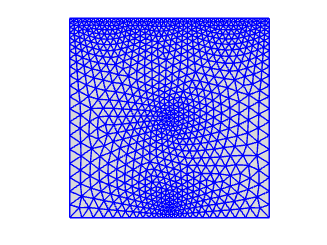

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');
axis equal off
exportgraphics(gca,'SquareInteriorNodes-MeshHedge.pdf','ContentType','vector');

###  Figure Mesh with Bubbles

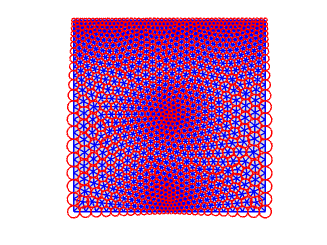

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

### Figure Mesh Quality Analysis

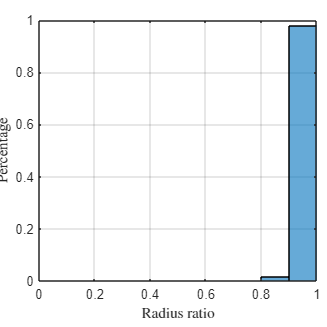

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on